## Q1:

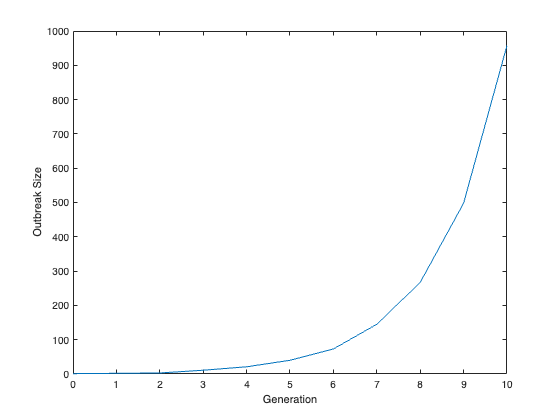

X = sim_branching_poisson(1.88, 10);
figure;
p = plot(0:1:10, X);
xlabel('Generation')
ylabel('Outbreak Size')

## Q2:

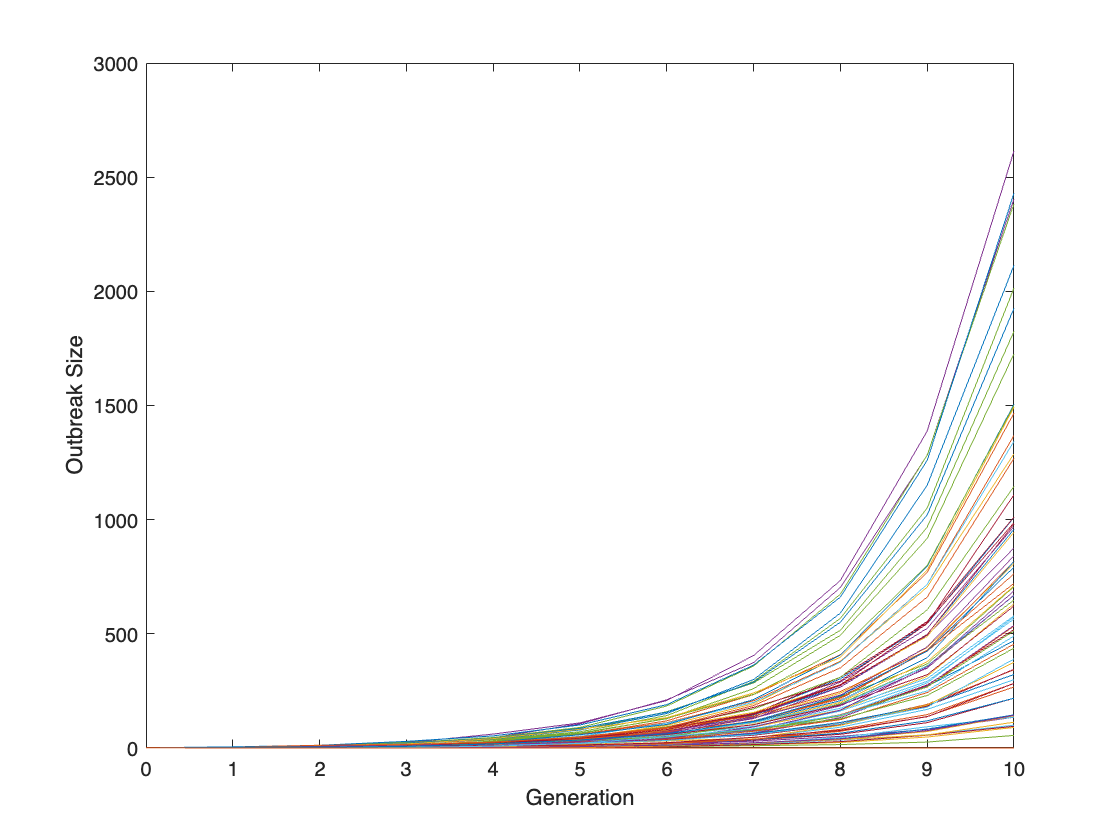

Xs = NaN(11, 100);
for i = 1:100
    Xs(:, i) = sim_branching_poisson(1.88, 10);
end
figure;
p = plot(0:1:10, Xs);
xlabel('Generation')
ylabel('Outbreak Size')

## Q3:

display(mean(Xs(11, :)))

  618.8800



## Q4:

display(sum(Xs(11,:)==0)/100)

    0.2500



## Q5:

lambda = 1.88;
display(sum(lambda.^(0:1:10)))

   1.1772e+03



## Q6:

cumsum([1 2 3])

ans =      1     3     6


cumsum([1 2 3; 4 5 6;7 8 9])

ans =      1     2     3
     5     7     9
    12    15    18


cumsum([1 2 3; 4 5 6],2)

ans =      1     3     6
     4     9    15



Xs_cum = cumsum(Xs);
mean_Xs_cum10 = mean(Xs_cum(end, :));
display(mean_Xs_cum10)

mean_Xs_cum10 = 1.3201e+03

## Q7a:

load('secondary_infections.mat');
params = nbinfit(counts);
disp(params)

    0.1226    0.0612



## Q7b:

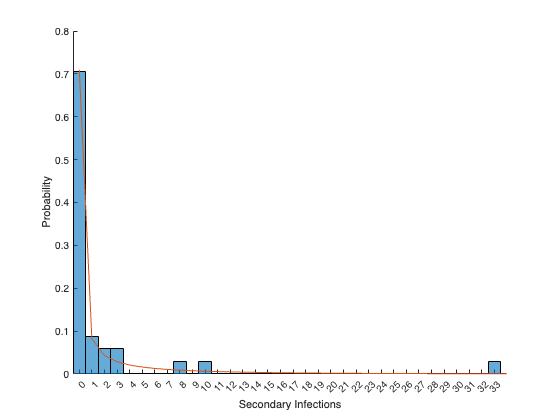

f = figure;
hold on;
histogram(counts, 'Normalization', 'probability');
plot(0:1:35, nbinpdf(0:1:35, params(1), params(2)));
xlim([-0.5 34])
xticks(0:1:33)
xlabel('Secondary Infections')
ylabel('Probability')
hold off;

## Q7c:

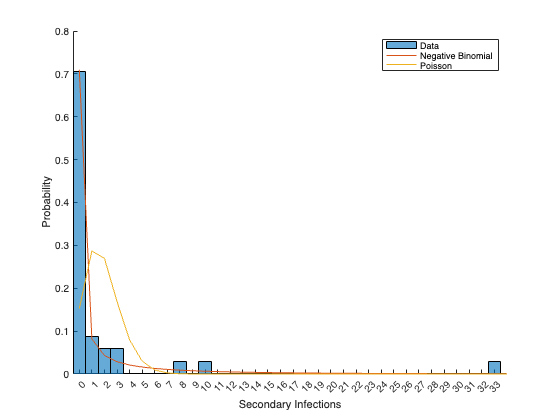

f = figure;
hold on;
histogram(counts, 'Normalization', 'probability');
plot(0:1:35, nbinpdf(0:1:35, params(1), params(2)));
xlim([-0.5 34])
xticks(0:1:33)
xlabel('Secondary Infections')
ylabel('Probability')
plot(0:1:35, poisspdf(0:1:35, 1.88))
legend('Data', 'Negative Binomial', 'Poisson');
hold off;

## Q8a:

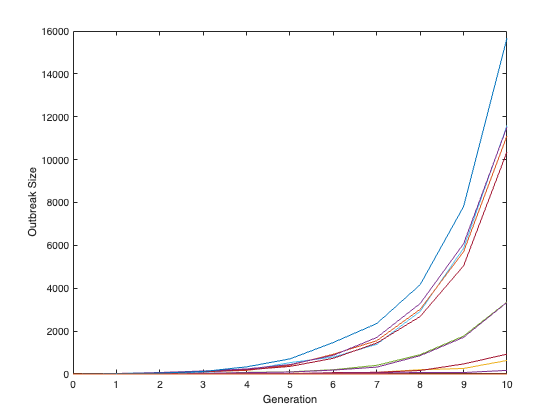

Xs_NB = NaN(11, 100);
for i = 1:100
    Xs_NB(:,i) = sim_branching_nbin(params(1), params(2), 10);
end
figure;
p = plot(0:1:10, Xs_NB);
xlabel('Generation')
ylabel('Outbreak Size')

display(mean(Xs_NB(11,:)))

  686.9600



## Q8b:

display(sum(Xs_NB(11,:)==0)/100)

    0.9000



## Q8c:

Xs_NB_cum = cumsum(Xs_NB);
mean_Xs_NB_cum10 = mean(Xs_NB_cum(end,:));
display(mean_Xs_NB_cum10)

mean_Xs_NB_cum10 = 1.4177e+03

function X = sim_branching_poisson(lambda, n_max)
 
X = zeros(1, n_max+1); % Initialize infection counts to zero
X(1) = 1; % Single infection at X0
 
for n = 1:n_max
    
    counts = 0;
 
    for i = 1:X(n)
        counts = counts + poissrnd(lambda);
    end
 
    X(n+1) = counts; % Total number of secondary infections
 
end
end 

function X = sim_branching_nbin(r, p, n_max)
 
X = zeros(1, n_max+1); % Initialize infection counts to zero
X(1) = 1; % Single infection at X0
 
for n = 1:n_max
    
    counts = 0;
 
    for i = 1:X(n)
        counts = counts + nbinrnd(r, p);
    end
 
    X(n+1) = counts; % Total number of secondary infections
 
end
end 

function M = laplace_gamma(s, alpha, beta)
M = (beta^alpha)/((s + beta)^alpha);
end